clear,clc,close
%%%%%%%%%%%%%%%%%生成训练集%%%%%%%%%%%%%%%%%
sampleSize = 300;
X = zeros(2,sampleSize);
Y = zeros(1,sampleSize);
for i = 1:sampleSize
    r = 250*rand;
    X(1,i) = -500+1000*rand;
    if rand <0.5
        X(2,i) = X(1,i)+r+30;
        Y(1,i) = 1;
    else
        X(2,i) = X(1,i)-r-30;
        Y(1,i) = -1;
    end
end
%%%%%%%%%%%%%%%%%生成测试集%%%%%%%%%%%%%%%%%
testSize = 50;
tX = zeros(2,testSize);
tY = zeros(1,testSize);
for i = 1:testSize
    r = 250*rand;
    tX(1,i) = -500+1000*rand;
    if rand <0.5
        tX(2,i) = tX(1,i)+r+30;
        tY(1,i) = 1;
    else
        tX(2,i) = tX(1,i)-r-30;
        tY(1,i) = -1;
    end
end
%%%%%%%%%%%%%%%%%按标签分类训练集，为最后的画图做准备%%%%%%%%%%%%%%%%%
classOne = 1;classTwo = -1;
[dimension,numOfsample] = size(X);
numOfClassOne = length(find(Y==1));
setOne = zeros(dimension,numOfClassOne);indexOfOne = 1;
setTwo = zeros(dimension,numOfsample - numOfClassOne);indexOfTwo = 1;
for i = 1:numOfsample
    if Y(1,i) == classOne
        setOne(:,indexOfOne) = X(:,i );
        indexOfOne = indexOfOne+1;
    else
        setTwo(:,indexOfTwo) = X(:,i );
        indexOfTwo = indexOfTwo + 1;
    end
end

numOfClassOne_t = length(find(tY==1));
TsetOne = zeros(dimension,numOfClassOne_t);indexOfOne = 1;
TsetTwo = zeros(dimension,testSize - numOfClassOne_t);indexOfTwo = 1;
for i = 1:testSize
    if tY(1,i) == classOne
        TsetOne(:,indexOfOne) = tX(:,i );
        indexOfOne = indexOfOne+1;
    else
        TsetTwo(:,indexOfTwo) = tX(:,i );
        indexOfTwo = indexOfTwo + 1;
    end
end

%%%%%%%%%%%%%%%%%计算拉格朗日对偶问题中的参量%%%%%%%%%%%%%%%%%
W = zeros(numOfsample);
for i = 1 : numOfsample
    for j = 1:numOfsample
        if j>=i
            W(i,j) = Y(1,i)*Y(1,j)*sum(X(:,i).*X(:,j));
        end
        if j<i
            W(i,j) = W(j,i);
        end
    end
end
M = ones(numOfsample,1);
%%%%%%%%%%%%%%%%%使用quadprog包计算alpha%%%%%%%%%%%%%%%%%
lb = zeros(numOfsample,1);
ub = [];
alpha = quadprog(W,-M,[],[],Y,0,lb,ub); %H = W,f = -M,A = [],b = [],Aeq = Y',beq = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


for i = 1:length(alpha)
    if alpha(i,1) < 1e-05
        alpha(i,1) = 0;
    end
end
alpha

alpha =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%%%%%%%%%%%%%%%%%计算最优决策面%%%%%%%%%%%%%%%%%
wStar = zeros(dimension,1);
for i  = 1:numOfsample
    wStar = wStar+alpha(i,1)*Y(1,i)*X(:,i);
end
bStar = 0;

for i = 1:numOfsample   %选取支撑向量
    if alpha(i,1) ~= 0 && Y(1,i) == classOne
        supportVector_ClassOne = X(:,i);
        
    elseif alpha(i,1) ~= 0 && Y(1,i) == classTwo
        supportVecto_ClassTwo = X(:,i);
    end
end
for i = 1: numOfsample
    if alpha(i,1) ~= 0
        bStar =bStar + alpha(i,1)*Y(1,i)*(sum(X(:,i).*supportVector_ClassOne)+sum(X(:,i).*supportVecto_ClassTwo));
    end
end
bStar = bStar*(-0.5);
wStar

wStar =        -0.0310197653804909
        0.0309932695591706


bStar

bStar =       -0.00567530692516982


predict = zeros(1,testSize);
for i = 1:testSize
    f = 0;
    for j = 1:numOfsample
        if alpha(j,1) ~=0
            f = f+alpha(j,1)*Y(1,j)*(sum(X(:,j).*tX(:,i)));
        end
    end
    f = f+bStar;
    if f >= 0
        f = 1;
    else
        f=-1;
    end
    predict(1,i) = f;
end
diff = predict - tY;
[~,c] = size(find(diff ~= 0))

c =      0


error = c/(testSize)

error =      0


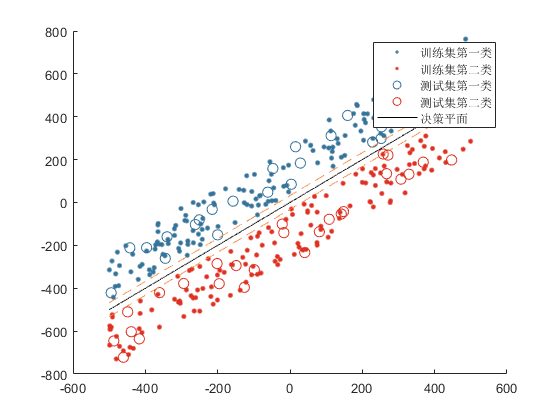

%%%%%%%%%%%%%%%二维数据的图像绘制%%%%%%%%%%%%%%%%%
scatter(setOne(1,:),setOne(2,:),120,[53 115 155]/255,'.')
hold on
scatter(setTwo(1,:),setTwo(2,:),120,[222 49 34]/255,'.')
scatter(TsetOne(1,:),TsetOne(2,:),60,[53 115 155]/255,'o')
scatter(TsetTwo(1,:),TsetTwo(2,:),60,[222 49 34]/255,'o')
if wStar(1,1) ~= 0&&wStar(2,1) ~= 0
    x1 = min(X(1,:))-1:0.1:max(X(1,:))+1;
    x2 = (-wStar(1,1)*x1/wStar(2,1)) - bStar/wStar(2,1);
    y = x2+1/wStar(2,1);
    z  = x2-1/wStar(2,1);
    plot(x1,x2,'-k')
    plot(x1,y,'--','Color',[244 125 48]/255)
    plot(x1,z,'--','Color',[244 125 48]/255)
    legend('训练集第一类','训练集第二类','测试集第一类','测试集第二类','决策平面')
elseif wStar(1,1) == 0
    x2 = (-bStar/wStar(2,1))*ones(1,10);
    y = x2+1/wStar(2,1);
    z  = x2-1/wStar(2,1);
    x1 = min(X(1,:))-1 + (-min(X(1,:))+max(X(1,:))+2)*rand(10,1);
    plot(x1,x2,'-k')
    plot(x1,y,'--g')
    plot(x1,z,'--g')
    legend('训练集第一类','训练集第二类','测试集第一类','测试集第二类','决策平面')
elseif wStar(2,1) == 0
    x1 = (-bStar/wStar(1,1))*ones(1,10);
    y = x1+1/wStar(1,1);
    z  = x1-1/wStar(1,1);
    x2 = min(X(2,:))-1 + (-min(X(2,:))+max(X(1,:))+2)*rand(10,1);
    plot(x1,x2,'-k')
    plot(y,x2,'--g')
    plot(z,x2,'--g')
    legend('训练集第一类','训练集第二类','测试集第一类','测试集第二类','决策平面')
end